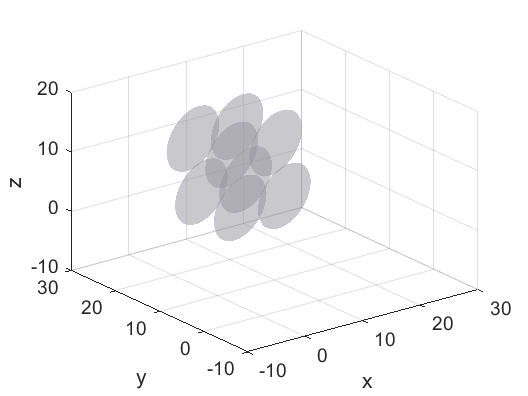

clear all
ax = axes('XLim',[-10 30],'YLim',[-10 30],'ZLim',[-10 20]);
view(3)

R11=5.546;
R31=2.95;
u31=[0.715;-0.531;-0.455];

[x1,y1,z1] = ellipsoid(2.54,8.05,4.79,R11,R11,R31,20);

hold on

h(1)=surf(x1,y1,z1,'FaceColor',[151, 150, 159]/256, ...
    'EdgeColor','none','FaceAlpha',0.3);

grid on
hold off


t1 = hgtransform('Parent',ax);
t2 = hgtransform('Parent',ax);
t3 = hgtransform('Parent',ax);
t4 = hgtransform('Parent',ax);
t5 = hgtransform('Parent',ax);
t6 = hgtransform('Parent',ax);
t7 = hgtransform('Parent',ax);
t8 = hgtransform('Parent',ax);


Rx = makehgtform('xrotate',-36.6*pi/180);
Ry = makehgtform('yrotate',117.1*pi/180);
Rz = makehgtform('zrotate',-36.6*pi/180);

Ta = makehgtform('translate',[7.665 0 0]);
Tb = makehgtform('translate',[-0.382 8.275 0]);
Tc = makehgtform('translate',[-1.824 -0.45 9.577]);
Tr1 = makehgtform('translate',[2.54 8.05 4.79]);


set(h,'Parent',t1);

h2 = copyobj(h,t2);
h3 = copyobj(h,t3);
h4 = copyobj(h,t4);
h5 = copyobj(h,t5);
h6 = copyobj(h,t6);
h7 = copyobj(h,t7);
h8 = copyobj(h,t8);

set(t1,'Matrix',Tr1*Rz*Ry*Rz/Tr1)
set(t2,'Matrix',Ta*Tr1*Rz*Ry*Rz/Tr1)
set(t3,'Matrix',Tc*Tr1*Rz*Ry*Rz/Tr1)
set(t4,'Matrix',Tb*Tr1*Rz*Ry*Rz/Tr1)
set(t5,'Matrix',Ta*Tb*Tr1*Rz*Ry*Rz/Tr1)
set(t6,'Matrix',Ta*Tc*Tr1*Rz*Ry*Rz/Tr1)
set(t7,'Matrix',Tb*Tc*Tr1*Rz*Ry*Rz/Tr1)
set(t8,'Matrix',Ta*Tb*Tc*Tr1*Rz*Ry*Rz/Tr1)


xlabel('x');
ylabel('y');
zlabel('z');
drawnow

for i = 1:360
   camorbit(1,0,'data',[0 0 1])

   drawnow
end